# **Week 1: Probability, statistics & Bayes theorem**

This live script provides an introduction to some probaiblity concepts and finishes with Bayes theorem. This forms the basis knowledge needed to go through Bayesian data analysis.

## **Starting with coin-flips**

We start considering likely the most exhausted example in probability textbooks: flipping a coin. This allows us to use a simple example as an introduction.

The Problem: We have a coin, with two sides (H: heads and T: tails) and we will flip it many times (N-times). On each flip, we take note of the face that comes up.

1) What is the set of all possible outcomes? 

Here we consider only two possible outcomes: Heads OR Tails.

Notice that whenever a heads occurs, a tails cannot occur. Therefore they are ***mutually exclusive***.

The set of all possible mutually exclusive outcomes is called the ***sample space***.

2) What is the *probability* of a coin landing heads-up?

In general, a ***probability*** is a way of assigning a number to a set of mutually exclusive possibilities. Probabilities follow a set of rules:

- Probabilites are bigger than zero $(
p>0)$

- The sum of all probabilities accross all event sin the sample space must be equal to 1 $(\sum_i p = 1)$

- For any two mutually exclusive events, the probability that one or the other occurs is the sum of their individual probabilities 

The probability of this coin to land heads-up will depend on its bias. If the coin is unbiased, then we would accept that the probability of heads is $\theta=0.5$, meaning there is a 50% chance this coin will be heads or tails on a single flip. Over many trials, we would therefore expect that our fair coin yields the same proportion of heads or tails.

We can simulate such an experiment in Matlab.

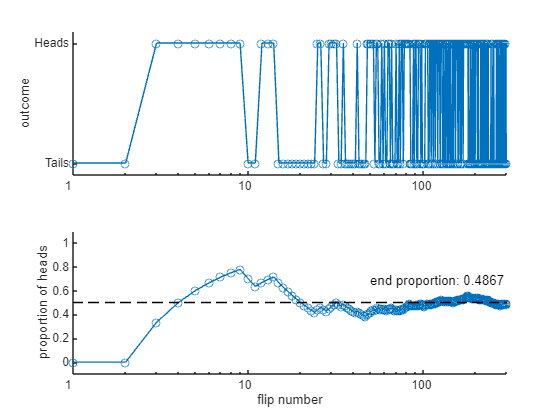

clf
rng(711); % make this repeatable

% We assume that our coin is unbiased i.e. theta = 0.5
theta   = 0.5;
% Now we make 500 flips
N       = 500;
% binornd --> bino = binomial , rnd
r       = binornd(1,theta,[1,N]);

% Show sequence of heads and tails
% we do this explicitly by first taking 1=Heads and 0=Tails, then reading
% as a character vector
% sequence = r;
% sequence(sequence==1) = 'H';
% sequence(sequence==0) = 'T';
% sequence = char(sequence)

% Now we plot the sequence
subplot(211)
plot(1:N,r,'-o');
set(gca,'xscale','log','ytick',[0,1],'yticklabel',{'Tails','Heads'},'xtick',[1,10,100,1e3],'xticklabel',[1,10,100,1e3])
xlim([0,N+1])
ylim([-0.1,1.1])
ylabel('outcome')
box off;

% Next we plot the running proportion of heads, meaning that at each flip
% we sum all the heads we had so far and divide by the number of flips. We
% can solve this by using the function 'cumsum' (cumulative sum).
Y           = cumsum(r)./(1:N);
subplot(212)
plot(1:N,Y,'-o');
hold on
plot([1,N],[theta,theta],'k--')
text(N/6,Y(end)+.2, ['end proportion: ' num2str(round(Y(end),4))] )
set(gca,'xscale','log','ytick',[0:0.2:1],'xtick',[1,10,100,1e3],'xticklabel',[1,10,100,1e3]);
xlim([0,N+1])
ylim([-0.1,1.1])
ylabel('proportion of heads')
xlabel('flip number')
box off;

The end proportion is not exactly the value of $\theta

$ we assumed, but we do see that its value is converging. By measuring the frequency of heads or tails using a ***random sample***, we are able to ***approximate*** the actual probability. Still notice this is a finite sample and therefore leads to an approximation. If we were to repeat this experiment infinitely many times, the result would indeed be the undrlying probability of 0.5. 

## **Moving to distributions**

Our next task is to move to a probability distribution. No longer a single number but many of them. In other words we want to see how probability gets allocated accross the set of possible outcomes. In our previous coin flipping example, this was simple, we had two outcomes, and our fair coing produced a value of $\theta=0.5$ for heads and $1-\theta=0.5$ fo tails (please, think about why the outcome for tails is treated as $1-\theta
$). But eventually, we will look at more complex datasets, where the set of possible outcomes are no longer discrete variables such as heads or tails, but continuous ones, such as reaction times, measured in seconds or sound localization errors measured in degrees.

We will first focus on ways to describe a distribution, both visually, and numerically and then will move to some common distributions we will use. 

#### Visualization: Histograms and cumulative probability plots

#### Central tendency: Mean, Median, Mode

#### Variability: Variance, Median, Mode

#### Bernoulli distribution

#### Binomial distribution

#### Normal distribution

#### Gamma distribution

#### Beta distribution

#### Uniform distribution

## **Bayes Theorem**